# CIFAR-10 con red convolucional

En este script vamos a tratar de resolver el problema de clasificar el objeto que hay en una imagen utilizando una red convolucional.

addpath(genpath('examples'));
SEED = 12345;
rng(SEED);

## Carga y normalización de los datos

[XTrain, YTrain, XTest, YTest] = ...
    loadCIFARData('examples/data/cifar-10');

XTrain = cast(XTrain, 'double') / 255;
XTest = cast(XTest, 'double') / 255;

## Subivisión del conjunto de entrenamiento para validación

[trainInd, valInd, ~] = dividerand(length(XTrain), .9, .1, .0);

XVal = XTrain(:, :, :, valInd);
YVal = YTrain(valInd);

XTrain = XTrain(:, :, :, trainInd);
YTrain = YTrain(trainInd);

## Creación de la red

layers = [
    imageInputLayer([32 32 3], 'Name', 'input')
    
    convolution2dLayer([3 3], 32, 'Padding', 'same', 'Name', 'conv11')
    reluLayer('Name', 'relu11')
    convolution2dLayer([3 3], 32, 'Padding', 'same', 'Name', 'conv12')
    reluLayer('Name', 'relu12')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pooling1')
    
    convolution2dLayer([3 3], 64, 'Padding', 'same', 'Name', 'conv21')
    reluLayer('Name', 'relu21')
    convolution2dLayer([3 3], 64, 'Padding', 'same', 'Name', 'conv22')
    reluLayer('Name', 'relu22')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pooling2')
    
    convolution2dLayer([3 3], 128, 'Padding', 'same', 'Name', 'conv31')
    reluLayer('Name', 'relu31')
    convolution2dLayer([3 3], 128, 'Padding', 'same', 'Name', 'conv32')
    reluLayer('Name', 'relu32')
    maxPooling2dLayer([2 2], 'Stride', [2 2], 'Name', 'max-pooling3')
    
    fullyConnectedLayer(10, 'Name', 'head')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

## Opciones de entrenamiento

miniBatchSize = 16;

options = trainingOptions('sgdm', ...
    'MiniBatchSize', miniBatchSize, ...
    'MaxEpochs', 8, ...
    'InitialLearnRate', .001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', miniBatchSize * 8, ...
    'Verbose', false, ...
    'Plots', 'training-progress' ...
);

## Entrenamiento

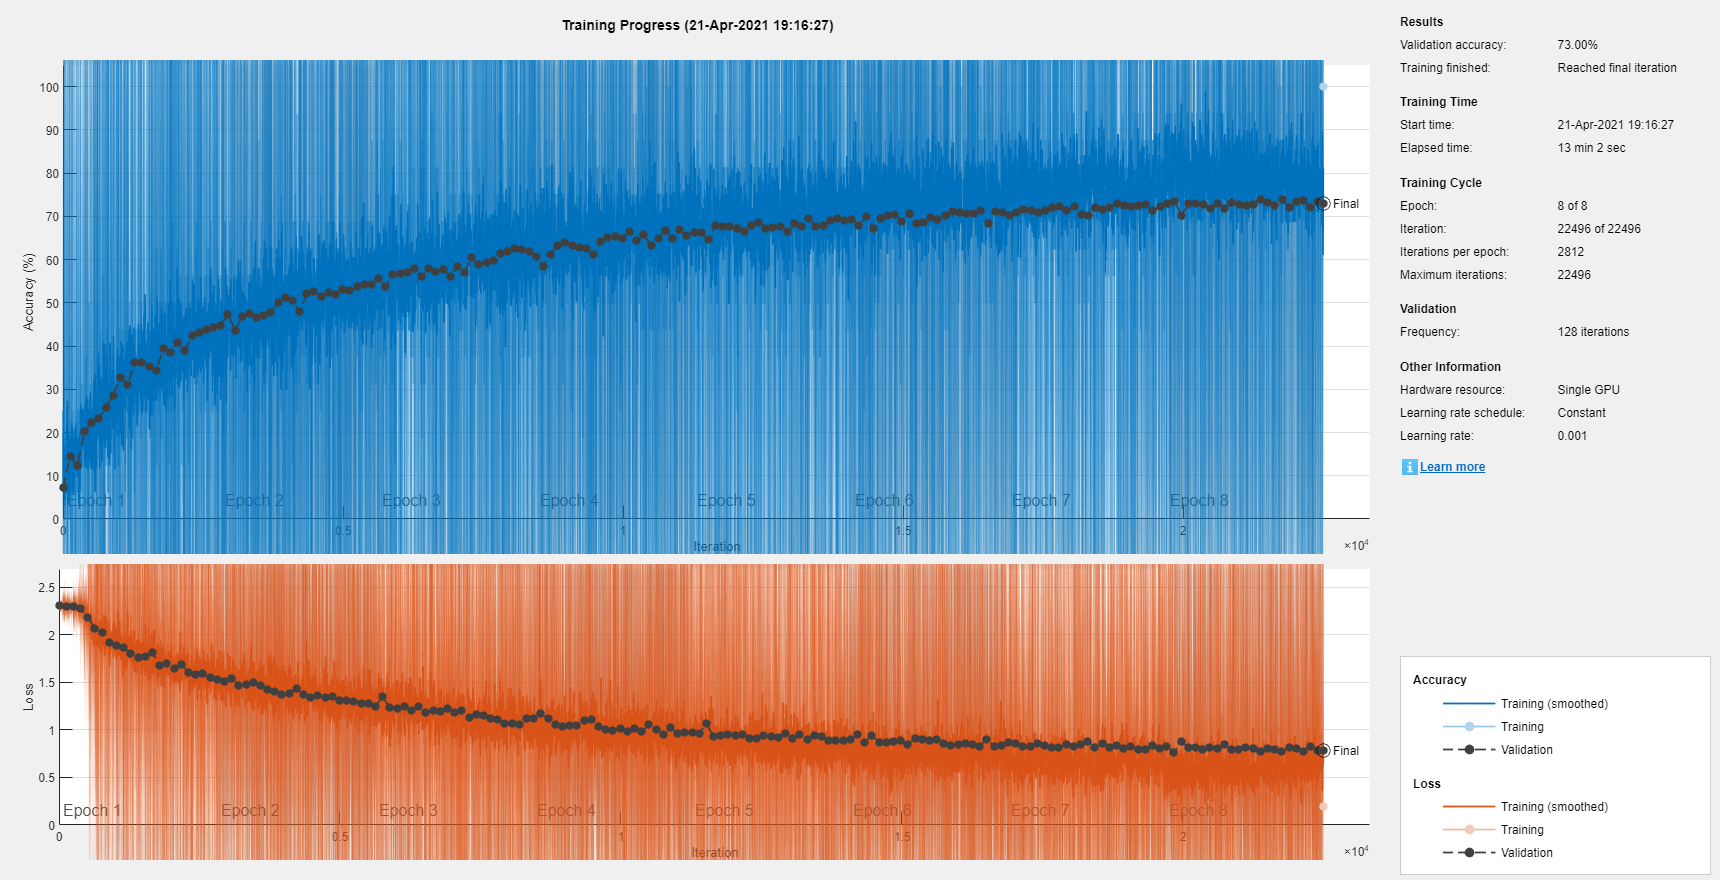

[net, info] = trainNetwork(XTrain, YTrain, layers, options);

save('examples/models/cifar10CNN.mat', 'net');
save('examples/models/cifar10CNNInfo.mat', 'info');

## Evaluación

cs = net.Layers(end).Classes;

probs = predict(net, XTest);
[~, YPred] = max(probs, [], 2);
YPred = cs(YPred);
acc = sum(YPred == YTest) / length(YTest);

fprintf("****************\n");

****************


fprintf("Accuracy: %0.4f\n", acc);

Accuracy: 0.7295


fprintf("****************\n");

****************


## Resultados

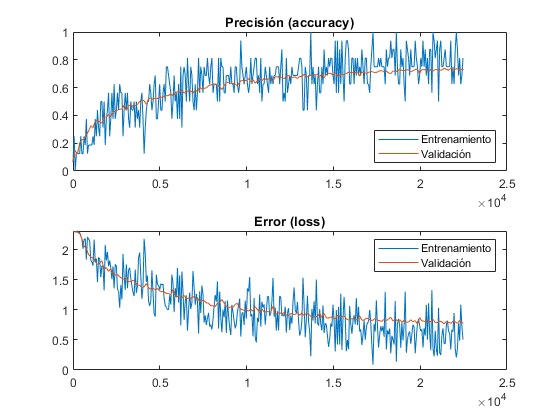

plotTraining(info, miniBatchSize * 4);